# Self-balancing robot parameters

% Motor: DFRobot DC Transmission Motor with Encoder - 6V - 160RPM

% Max stall torque = 0.08 [Nm] 
% Max stall current = 2.8 [A]


% From datasheet: No-load current @ 6V: 0.17A -> trovo da qui la R

m = 0.4;         % massa del robot [kg]
g = 9.81;      % costante gravitazionale [m/s^2]
l = 0.4;       % altezza robot [m]

KePhi = 0.336; %(Va_max-Ra*Ia)*1/Omega_max %[V*s]
Ra = 3.7;    % armature winding resistance [ohm] MEASURED
La = 1e-2;      % armature winding inductance [H] -> da misurare

beta = 1e-5;   % coefficiente di attrito viscoso aria [Nms]
J = m*l^2;     % momento d'inerzia del sistema [kg*m^2]

k_gear = 120; % gear ratio

max_v = 6*1.2;   % tensione massima applicabile

## DC Motor Model

V(s) = Ra Ia + KePhi * Omega + s L Ia

## Controller design (PID)

% mi trovo la matrice "A", vettori "b" e "c" per trovare la funzione di trasferimento del sistema
s = tf('s');

A = [-Ra/La 0 -KePhi/La; 0 0 1; KePhi/(m*l^2) -g/l*cos(pi) -beta/(m*l^2)];

b = [1/La; 0; 0];

c = [0, 1, 0];

% identity matrix
I = [1 0 0; 0 1 0; 0 0 1];

% Calculations
MfD = s*I - A; % matrix for determinant calculations
pol_car = s*( MfD(1,1)*MfD(3,3) - MfD(1,3)*MfD(3,1) ) + MfD(1,1)*MfD(3,2);

% transfer function

G = tf(c*(s*I-A)^(-1)*b);
p = pole(G);

% neglecting the hf pole
[num_W, den_W] = tfdata(G, 'v');
G_appr = num_W(4)/((s - p(2))*(s - p(3)));

## Requirements: tempo di salita e overshoot

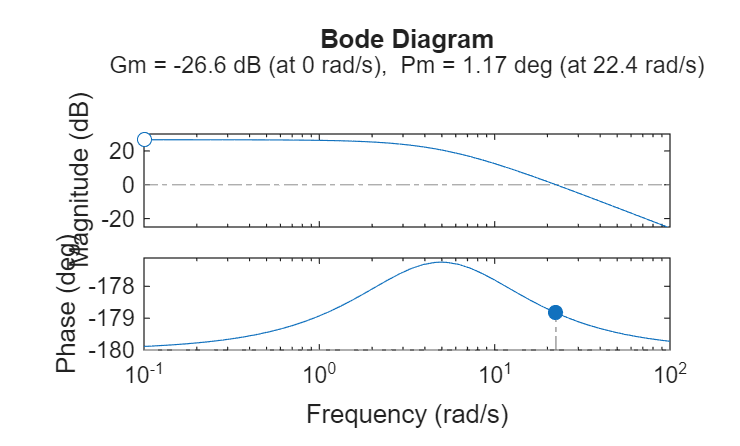

ts = 1e-3; % rise time
M = 0;  % overshoot: percentuale 7.5/6 (massima tensione che può accettare) = 0.2 -> margine di sicurezza

fct = 2/(ts*2*pi);
pmt = 1.04 - 0.8*M;

opt = pidtuneOptions;
opt.PhaseMargin = pmt;

margin(G_appr);

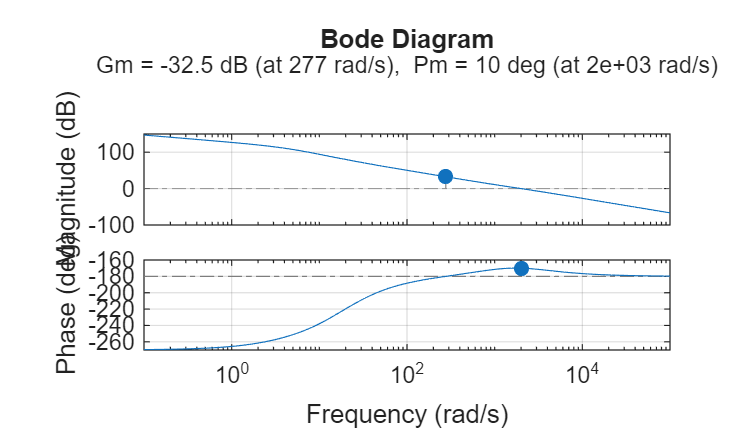


[gi, info] = pidtune(G_appr, 'pidf', 2*pi*fct, opt);    %'pidf' così ho il filtro nella parte derivativa

reg = gi.Kp + gi.Ki/s + gi.Kd*s/(1+s*gi.Tf);
[Nreg, Dreg] = tfdata(reg, 'v');    % 'v' per averceli in vettore
margin(reg*G_appr);
grid on;